# **Differentiability of One-Variable Functions**

## **1. Average Rate of Change**

Consider the behavior of a function $f(x)$, $x\in\mathbb{R}$. 


$$\frac{f(b)-f(a)}{b-a},
\quad
b \ne a$$


is said to the average rate of change of $f(x)$ between $x=a$ and $x=b$. This is the slope of the line connecting two points A$\bigl(a,f(a)\bigr)$ and B$\bigl(b,f(b)\bigr)$ on the curve given by $y=f(x)$.

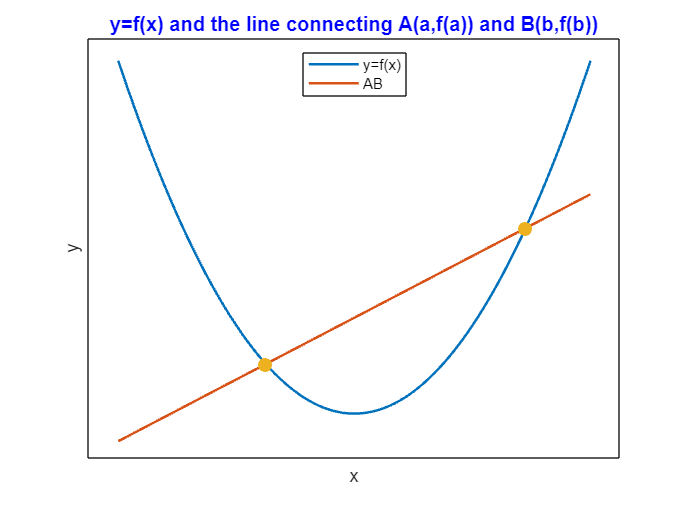

a =-1.5; b =2.9;
p0=zeros(1,2);
q0=zeros(1,2);
p0(1,1)=a;
q0(1,1)=a^2;
p0(1,2)=b;
q0(1,2)=b^2;

x0 = -4:0.05:4;
f0=x0.^2;
g0=(a+b)*x0-a*b;

Y1=plot(x0,f0,x0,g0,'LineWidth',1.5);
   ylim([-2 17])
   xlim([-4.5 4.5])
   title('y=f(x) and the line connecting A(a,f(a)) and B(b,f(b))','Color','blue','FontSize',12)
   xlabel('x')
   xticks([])
   ylabel('y')
   yticks([])
hold on
   sz0=70;
Y2=scatter(p0,q0,sz0,'filled');
hold off
legend([Y1],{'y=f(x)','AB'},'Location','north')

## 2. Differentiability

Fix $a\in\mathbb{R}$, and consider the behavior of $f(x)$ near $x=a$. 

We say that $f(x)$ is differentiable at $x=a$ if there exists $\alpha\in\mathbb{R}$ such that 


$$\frac{f(x)-f(a)}{x-a} \rightarrow \alpha
\quad
(x \rightarrow a).$$


In this case the real number $\alpha$ is said to be the derivative of $f(x)$ at $x=a$ and denoted by 


$$f^\prime(a), \quad \frac{df}{dx}(a).$$


Set 


$$R(x):=f(x)-\{f(a)+\alpha(x-a)\},$$


that is, 


$$f(x)=f(a)+\alpha(x-a)+R(x),
\quad
\frac{R(x)}{x-a}=\frac{f(x)-f(a)}{x-a}-\alpha.$$


Then $f(x)$ is differentiable at $x=a$ if and only if there exist $\alpha\in\mathbb{R}$ and a function $R(x)$ such that 


$$f(x)=f(a)+\alpha(x-a)+R(x),
\qquad
\frac{R(x)}{x-a} \rightarrow 0 
\quad
(x \rightarrow a).$$


Let us consider the meaning of the differentiability below. 

## 3. The meaning of $R(x)/(x-a) \rightarrow 0 
\quad
(x \rightarrow a)$

The condition $R(x)/(x-a) \rightarrow 0 
\quad
(x \rightarrow a)$ means that $R(x)$ goes to $0$ as $x \rightarrow a$ faster than the linear funtion of $x-a$.  Set $t=|x-a|$. Observe the speed of convergence of $t$ and $t^p$with $p>0$ as  $t \downarrow 0$. Let $C_1$ and $C_2$ be positive constants. 

When p>1


$$\frac{C_1t^p}{C_2t}=\frac{C_1}{C_2}t^{p-1} \rightarrow 0
\quad
(t \downarrow 0).$$


When p<1


$$\frac{C_1t^p}{C_2t}=\frac{C_1}{C_2}t^{-(1-p)} \rightarrow \infty
\quad
(t \downarrow 0).$$


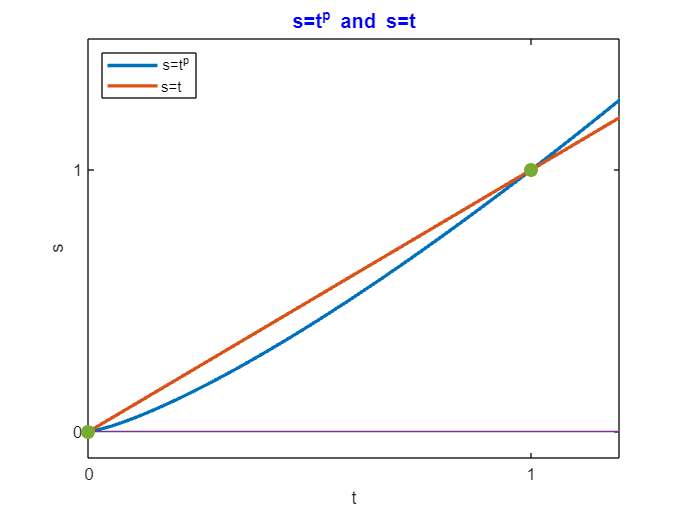

p = 1.3;
p0=zeros(1,2);
q0=zeros(1,2);
p0(1,1)=0;
p0(1,2)=1;
q0(1,1)=0;
q0(1,2)=1;
t1 = 0:0.01:1.2;
supersub=t1.^p;
linear=t1;

Z1=plot(t1,supersub,'LineWidth',2);
    ylim([-0.1 1.5])
    xlim([0 1.2])
    title('s=t^p and s=t','Color','blue','FontSize',12)
    xticks([0 1])
    xticklabels({'0','1'})
    xlabel('t')
    yticks([0 1])
    yticklabels({'0','1'})
    ylabel('s')
hold on
Z2=plot(t1,linear,'LineWidth',2);
Z3=plot(t1,zeros(121),'LineWidth',0.1);
sz1 = 70;
Z4=scatter(p0,q0,sz1,'filled');
hold off 
legend([Z1 Z2],{'s=t^p','s=t'},'Location','northwest');

## 4. All the lines passing through $\bigl(a,f(a)\bigr)$

We know tthat $f(x)$ is differentiable at $x=a$ if  


$$f(x)
=
\ 
\text{[first order polynomial passing through $\bigl(a,f(a)\bigr)$]}
\ + \  
\text{[error far smaller than $x-a$]}$$


as $x \rightarrow a$. Denote the first order polynomial by 


$$h(x)=f(a)+f^\prime(a)(x-a).$$


Moreover we consider lines passing through $\bigl(a,f(a)\bigr)$ with an arbitrary slope $b\in\mathbb{R}$:


$$g(x)=f(a)+b(x-a),
\quad
b\in\mathbb{R},$$


$h(x)$ is the special case of $g(x)$ with $b=f^\prime(a)$. 

Consider how fast the differences $f(x)-g(x)$ and $f(x)-h(x)$ go to $0$ as $x \rightarrow a$.  

If $b \ne f^\prime(a)$ then as fast as $x-a$: 

$f(x)-g(x)=\bigl(f^\prime(a)-b\bigr)(x-a)+R(x)$.

If $b = f^\prime(a)$ then faster than $x-a$: 

$f(x)-h(x)=R(x)$.

So the line given by $y=h(x)$ is a special line for $y=f(x)$ at $\bigl(a,f(a)\bigr)$. The line given by $y=h(x)$ is said to be the tangential line of $y=f(x)$ at $\bigl(a,f(a)\bigr)$. Roughly spaeking,** we say that **$f(x)$** is differentiable at **$x=a$** if there exists a unique tangential line of **$y=f(x)$** at **$\bigl(a,f(a)\bigr)$. 

## 5. Example $f(x)=x^2$


$$g(x)=a^2+b(x-a), 
\quad
h(x)=a^2+2a(x-a), $$



$$f(x)-g(x)=(2a-b)(x-a)+(x-a)^2, 
\quad
f(x)-h(x)=(x-a)^2.$$


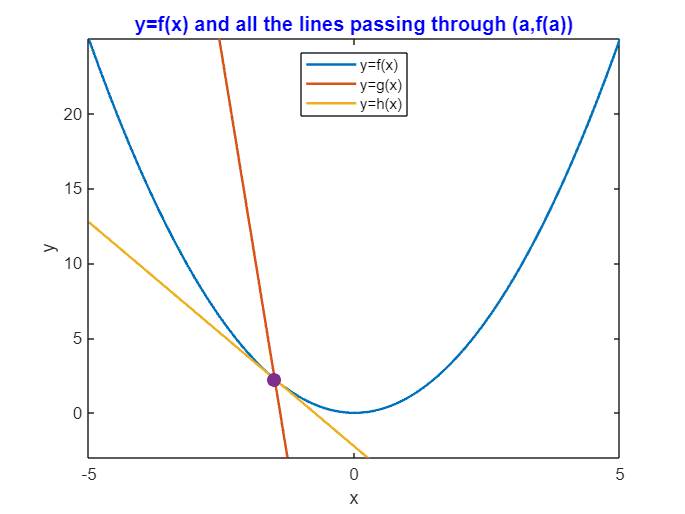

a =-1.5;  b = -21.8;
p1=zeros(1,1);
q1=zeros(1,1);
p1(1,1)=a;
q1(1,1)=a^2;

x1 = -5:0.01:5;
f=x1.^2;
g=a^2+b*(x1-a);
h=a^2+2*a*(x1-a);

X1=plot(x1,f,'LineWidth',1.5);
    ylim([-3 25])
    xlim([-5 5])
    title('y=f(x) and all the lines passing through (a,f(a))','Color','blue','FontSize',12)
    xticks([-5 0 5])
    xticklabels({'-5','0','5'})
    xlabel('x')
    yticks([0 5 10 15 20])
    yticklabels({'0','5','10','15','20'})
    ylabel('y')
%    legend('y=f(x)','y=g(x)','y=h(x)','Location','north')
hold on
X2=plot(x1,g,'LineWidth',1.5);
X3=plot(x1,h,'LineWidth',1.5);
sz2=70;
X4=scatter(p1,q1,sz2,'filled');
hold off
legend([X1 X2 X3],{'y=f(x)','y=g(x)','y=h(x)'},'Location','north')